# **Examen parcial 1: Control y Sistemas 2025**

## **Requerimientos de Ingeniería**

Se recuperan las señales de dos sensores x_c(t) y x_r(t). La primera es una onda senoidal y la segunda una onda rectangular. Ambas fueron tratadas con un filtro antialiasing pero las mismas acarrean unas perturbaciones particulares que se quieren remover. Debemos realizar el tratamiento correspondiente con el método oversampling para lograr ingresarlas a un sistema de cómputo discreto (procesador, DSP) donde se desea realizar operaciones con la información que traen. Para ello es necesario asegurarse de remover el ruido que tienen y hacerlo logrando mantener la forma de la onda, acotar el desfasaje del resultado y tener una buena relación ruido-señal. Buscamos que el procesador realice los cálculos confiando que la señales que proveemos traen la información real.   

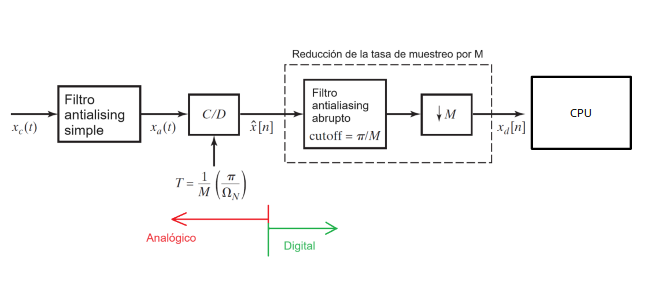

## **Antes de iniciar los cálculos y el diseño**

Describa lo que interpreta del requerimiento de la aplicación y cómo procederá para resolver reducido a tres simples pasos de manera descriptiva y simple.  

Nuestro procesador, que va a ser el encargado de realizar las operaciones entre las señales de los dos sensores x_c(t) y y x_r(t), necesita de lo siguiente para que nosotros podamos confiar que el resultado que nos da es acorde a la información real:

Si bien se aplica un filtro antialiasing, por ser un filtro tipo simple el ruido no se va a eliminar al completo, solamente se va a atenuar un poco. Esto sucede porque el filtro antialiasing simple hace que la transición sea suave, tiene una banda pasante alta de forma tal que no distorsione la señal útil y la banda de transición debe ser tal que la banda suprimida comience en un valor de frecuencia mayor que la mayor frecuencia de nuestra señal útil, pero en esta banda de transición es probable que encontremos ruido. 

Una vez aplicado el filtro antialiasing simple, convertimos la señal continua al dominio discreto aplicando Oversampling. Pasamos al dominio discreto ya que en él podemos usar filtros digitales y éste puede mucho más abrupto que en un filtro analógioc.  Al aplicar la técnica de Oversampling, lo que hacemos es aumentar la frecuencia de muestro original en una cantidad M de forma tal que en el dominio de la frecuencia, como ahora la señal útil junto al ruido es periódica y se va a repetir cada 2pi, nos aseguramos que no haya solapamiento de la señal útil y evitar así el antialiasing. Cabe aclarar que en este paso puede haber solapamiento del ruido pero no es de importancia ya que luego se eliminará. 

Una vez eliminado el ruido, se aplicará decimación para disminuir la tasa de muestreo y asi disminuir también un costo computacional innecesario sin preocuparnos por el aliasing. 

En resumen, los 3 pasos son:

- Aplicar filtro Antiliasing simple para proteger la banda útil y atenuar algo de ruido de alta frecuencia

- Oversampling y filtrado digital abrupto para eliminar el ruido remanente

- Decimación 

## Descripción de las señales

Una de las señales tiene una frecuencia máxima de 1 Hz, la otra de 5Hz; y se desea usar un filtro antialiasing analógico **simple** [con atenuación de -3 dB en 100 Hz y -60 dB en 200 Hz (no es necesario diseñar este filtro analógico)]. 

Ambas señales son interferidas por ruidos distintos. La señal senoidal acarrea una componente de ruido senoidal del 50Hz. En cambio la señal rectangular es atacada por un ruido gaussiano tal que la relación señal-ruido entre la señal rectangular y el ruido es de 15dB.

clc
clear
close all
%% Frecuencia de signals
frequency_xc = 1;        % [Hz] frequency of signal 1
frequency_xr = 5;       % [Hz] frequency of signal 2
frequency_noise = 50      % [Hz]

frequency_noise = 50

% Definir SNR ruido onda rectangular (en dB)
SNR_dB = 1;

## Muestreo y señales

## Determine la mínima frecuencia de muestreo

Necesitamos que la etapa de muestreo evite errores por aliasing y que podamos recuperar la información que tiene la señal.

Para que el filtro pueda atenuar al menos -60dB sin distorsionar la señal útil necesitamos que su banda de parada coincida (o este por encima) de la frecuencia de Nyquist. Por lo tanto, como la atenuación de -60dB se encuentra en 200Hz, la frecuencia de Nyquist debe ser fs/2 >= 200Hz. Siendo fs la frecuencia de muestreo.

Entonces, concluimos que la mínima frecuencia de muestreo debe ser de 400Hz. 

## Declaración de parámetros de muestreo

## Parámetros de las señal

sampling_rate = 400 ;       % [Hz] how often the signal is sampled
fs = sampling_rate

fs = 400

## Rango de tiempo y vector de tiempo

start_time = 0;         % [s] beginning of the time window
end_time = 1;         % [s] end of the time window

t = start_time : 1/sampling_rate : end_time;  % [s] time points at which the signal is sampled

## Construcción de las señales y ruidos

## Señal 1, señal 2 y ruidos

Construya usando su vector de tiempo las señales senoidales y rectangular. Construya los ruidos y apliquelos a las señales originales.


% 2π * frequency [rad/s] * time [s] → [rad] → sin(...) → unitless amplitude
signal_xc = sin(2 * pi * frequency_xc * t);         % [1] sine wave values (unitless amplitude)
signal_xr = square(2 * pi * frequency_xr * t);

max(signal_xc)

ans = 1

min(signal_xr)

ans = -1

% 1. Elige un índice intermedio (para evitar los bordes del vector)
idx = round(length(signal_xc)/2);

% 2. Toma dos valores consecutivos y calcula la diferencia
x_n   = signal_xc(idx);
x_np1 = signal_xc(idx+1);
delta = abs(x_np1 - x_n);

% 3. Muéstralos por pantalla
fprintf('x[%d]     = %.8f\n', idx,   x_n);

x[201]     = 0.00000000


fprintf('x[%d]     = %.8f\n', idx+1, x_np1);

x[202]     = -0.01570732


fprintf('delta    = %.8f (valor absoluto de la variación)\n', delta);

delta    = 0.01570732 (valor absoluto de la variación)



% ruido_xc y ruido_xr
noise_xc = sin(2*pi*frequency_noise*t);

rms_xr   = rms(signal_xr);                      % RMS de la señal cuadrada 
noise_rms = rms_xr / (10^(SNR_dB/20));          % RMS del ruido para SNR=15 dB
noise_xr = noise_rms * randn(size(t));         % ruido Gaussiano escalado


% Calcular 
signal_noise_xc = signal_xc + noise_xc;        % [1] signal with additional noise
signal_noise_xr = signal_xr + noise_xr;	    % [1] signal with additional noise



## Plot de señales en el dominio del tiempo

Realice un plot de la señales sin la perturbación, el ruido y la señal con la perturbación agregada. 

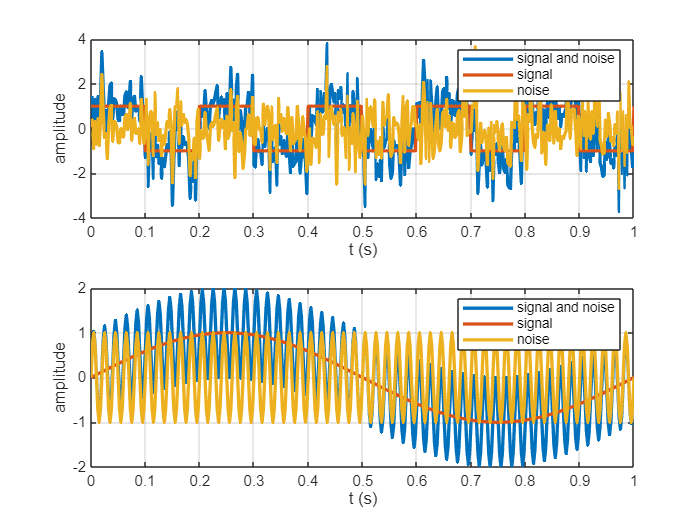

figure
hold on
subplot(2,1,1)
plot(t, [signal_noise_xr; signal_xr; noise_xr], 'linewidth', 2)
xlabel('t (s)')
ylabel('amplitude')
legend('signal and noise', 'signal', 'noise')
grid on
subplot(2,1,2)
plot(t, [signal_noise_xc; signal_xc; noise_xc], 'linewidth', 2)
xlabel('t (s)')
ylabel('amplitude')
legend('signal and noise', 'signal', 'noise')
grid on

## Plot de señales en el dominio de la frecuencia

Realice un plot de la señales sin la perturbación agregada en el dominio de la frecuencia para lograr ver sus componentes. 

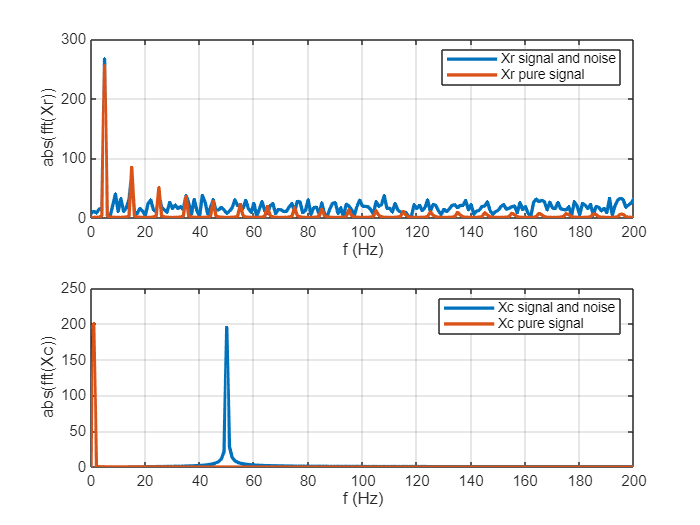

Xr = abs(fft(signal_noise_xr));
Xr_p = abs(fft(signal_xr));          % ← FFT de la señal pura
Xc = abs(fft(signal_noise_xc));
Xc_p = abs(fft(signal_xc));          % ← FFT de la señal pura


figure
subplot(2,1,1)
plot(linspace(0, fs/2, round(length(Xr)/2)), Xr(1:round(length(Xr)/2)), 'linewidth', 2);
hold on
plot(linspace(0, fs/2, round(length(Xr_p)/2)), Xr_p(1:round(length(Xr_p)/2)), 'linewidth', 2);
xlabel('f (Hz)')
ylabel('abs(fft(Xr))')
legend('Xr signal and noise','Xr pure signal')
grid on

subplot(2,1,2)
plot(linspace(0, fs/2, round(length(Xc)/2)), Xc(1:round(length(Xc)/2)), 'linewidth', 2);
hold on
plot(linspace(0, fs/2, round(length(Xc_p)/2)), Xc_p(1:round(length(Xc_p)/2)), 'linewidth', 2);
xlabel('f (Hz)')
ylabel('abs(fft(Xc))')
legend('Xc signal and noise','Xc pure signal')
grid on

## Conclusiones

***La señal tiene más información representada en el dominio del tiempo y o de la frecuencia?***

La información, al menos en señal senoidal, tiene más información útil en el dominio de la frecuencia ya que nos muestra especificamente en que frecuencia encontramos el ruido que distorsiona la señal. Analizando únicamente el dominio del tiempo  no podemos hacer un análisis muy significativo ya que el ruido como tiene amplitud constante, si eliminamos la componente de frecuencia ya es suficiente para eliminarlo. 

el domi

*** Esto puede influir en la elección del filtro?***

## Filtrado y Decimación

## Las características del decimador y del filtro digital que debe implementar

Deberá elegir entre alguna de las implementaciones de filtros posibles. Fundamente porque realizó dicha elección.

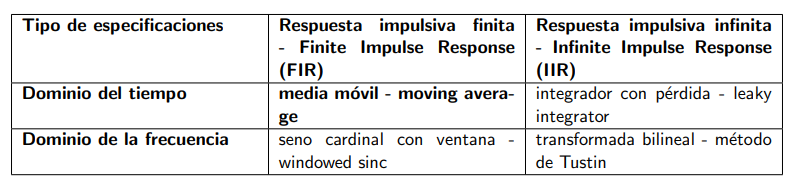

## Diseño del filtro FIR onda senoidal


% Como usamos un filtro FIR, y este filtro no tiene polos, el denominador a
% sera igual a 1. El numerador lo haremos de la siguiente forma: determino
% la frecuencia del primer cero, haciendolo coincidir con la frecuencia
% donde se encuentra el ruido de 50 Hz que queremos eliminar

f1cero = 50;
M = fs / f1cero;
b_xc = ones(1,M) * 1/M;
a = 1;
filtered_signal_xc = filter(b_xc, a, signal_noise_xc);






## Polos, ceros y diagrama de bode

Realice un plot para ver ceros, polos y el diagrama de bode del filtro

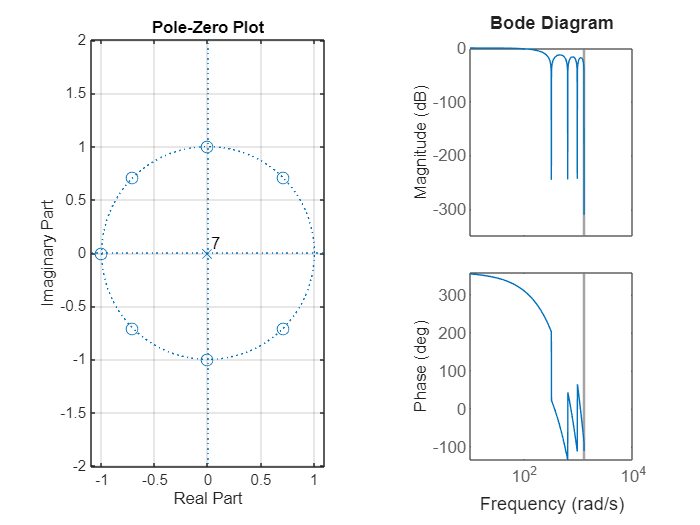

figure
subplot(1,2,1)
zplane(b_xc,a)
grid on
subplot(1,2,2)
bode(filt(b_xc, a, 1/sampling_rate))
grid on

## Decimación onda senoidal

Realice una decimación de la onda filtrada, elegiendo bien la nueva frecuencia de muestreo.

fs = sampling_rate;
fs_new = 50; % Hz
subsampled_filt_signal_xc = filtered_signal_xc(1:round(fs/fs_new):end);
subsampled_t = t(1:round(fs/fs_new):end);


## Análisis en frecuencia y tiempo onda senoidal

Haga un plot en frecuencia de para ver si eliminó las componentes que buscaba eliminar. 

## Código análisis en frecuencia

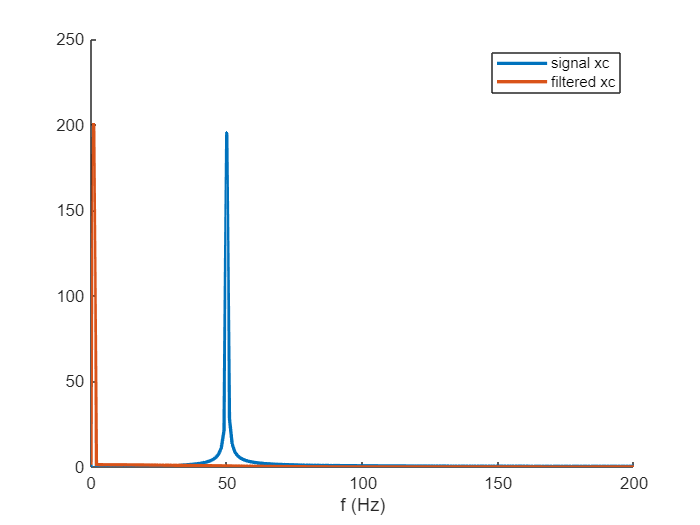


X = abs(fft(signal_noise_xc));
X_filt = abs(fft(filtered_signal_xc));
figure
hold on
plot(linspace(0, fs/2, round(length(X)/2)), X(1:round(length(X)/2)), 'linewidth', 2);
plot(linspace(0, fs/2, round(length(X_filt)/2)), X_filt(1:round(length(X_filt)/2)), 'linewidth', 2);
legend('signal xc', 'filtered xc')
xlabel('f (Hz)')

## Código análisis en tiempo

Grafique la señal original, la que tiene ruido y la filtrada para ver una compararción. La señal filtrada tiene mucho desfasaje? en tiempo o en forma? Explique

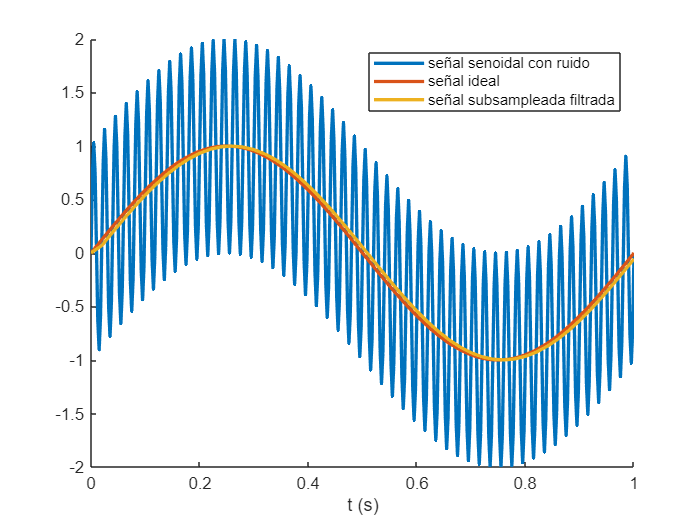

figure
hold on
plot(t, [signal_noise_xc; signal_xc], 'linewidth', 2)
plot(subsampled_t, subsampled_filt_signal_xc, 'linewidth', 2)
xlabel('t (s)')
legend('señal senoidal con ruido', 'señal ideal', 'señal subsampleada filtrada')

## Cálculo de SNR para score del filtro de onda senoidal

subsampled_signal_xc = signal_xc(1:round(fs/fs_new):end);
SNR_xc = 20*log10(rms(subsampled_signal_xc)/rms(subsampled_filt_signal_xc - subsampled_signal_xc))

SNR_xc = 25.1995

if SNR_xc < 10
    disp(['Nota Ej 1 = 4'])
elseif SNR_xc < 13
    disp(['Nota Ej 1 = 5'])
elseif SNR_xc < 16
    disp(['Nota Ej 1 = 6'])
elseif SNR_xc < 19
    disp(['Nota Ej 1 = 7'])
elseif SNR_xc < 22
    disp(['Nota Ej 1 = 8'])
else
    disp(['Nota Ej 1 = 9'])
end

Nota Ej 1 = 9


## Resultados onda senoidal

*** ¿La señal filtrada tiene mucho desfasaje? ¿distorsiona la forma? Explique sus resultados***

La señal filtrada tiene desfasaje pero no es muy notable, la forma no se distoriosiona. El desfasaje ocurre porque el filtro de Media Móvil introduce un desfasaje de M muestras, siendo M el tamaño de la ventana. Entre mayor es M mayor ruido de alta frecuencia vamos a poder eliminar a cambio de introducir un desfasaje en la señal filtrada respecto a la señal original. 

## Diseño del filtro FIR onda cuadrada


f_c = 70;                     % corte a 15 Hz
M_c   = round( fs / f_c );      % e.g. 400/15
b   = ones(1, M_c)/M_c; 

filtered_signal_xr = filter(b, a, signal_noise_xr);



## Polos, ceros y diagrama de bode

Realice un plot para ver ceros, polos y el diagrama de bode del filtro

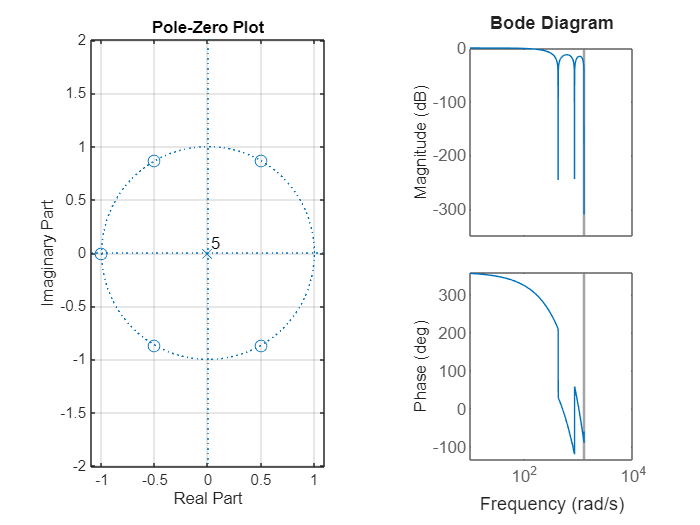

figure
subplot(1,2,1)
zplane(b,a)
grid on
subplot(1,2,2)
bode(filt(b, a, 1/sampling_rate))
grid on

## Decimación onda cuadrada

Realice una decimación de la onda filtrada, elegiendo bien la nueva frecuencia de muestreo.

subsampled_filt_signal_xr = filtered_signal_xr(1:round(fs/fs_new):end);

## Análisis en frecuencia y tiempo onda cuadrada

Haga un plot en frecuencia de para ver si eliminó las componentes que buscaba eliminar. 

## Código análisis en frecuencia

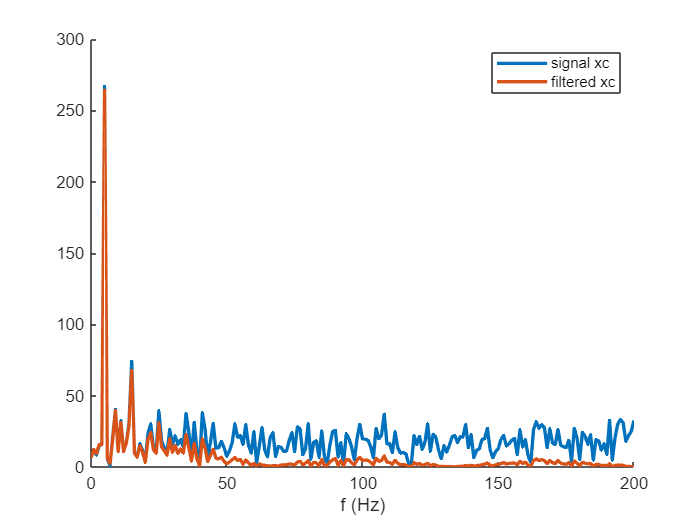

X = abs(fft(signal_noise_xr));
X_filt = abs(fft(filtered_signal_xr));
figure
hold on
plot(linspace(0, fs/2, round(length(X)/2)), X(1:round(length(X)/2)), 'linewidth', 2);
plot(linspace(0, fs/2, round(length(X_filt)/2)), X_filt(1:round(length(X_filt)/2)), 'linewidth', 2);
legend('signal xc', 'filtered xc')
xlabel('f (Hz)')

## Código análisis en tiempo

Grafique la señal original, la que tiene ruido y la filtrada para ver una compararción. 

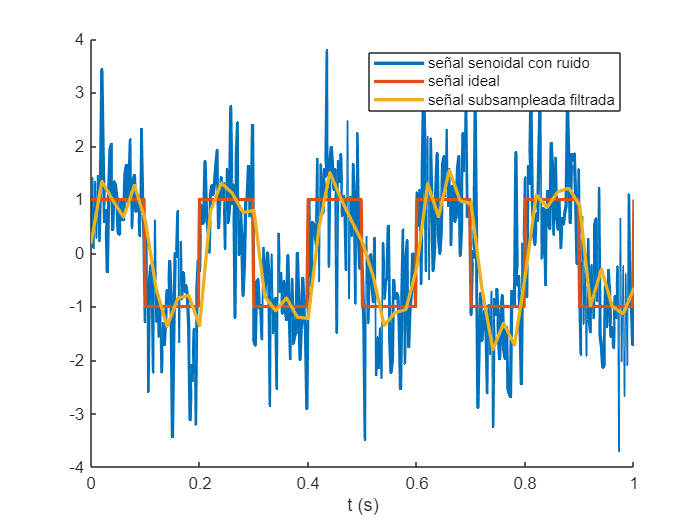

figure
hold on
plot(t, [signal_noise_xr; signal_xr], 'linewidth', 2)
plot(subsampled_t, subsampled_filt_signal_xr, 'linewidth', 2)
xlabel('t (s)')
legend('señal senoidal con ruido', 'señal ideal', 'señal subsampleada filtrada')

subsampled_signal_xr = signal_xr(1:round(fs/fs_new):end);
SNR_xr = 20*log10(rms(subsampled_signal_xr)/rms(subsampled_filt_signal_xr - subsampled_signal_xr))

SNR_xr = 1.4498

if SNR_xr < 10
    disp(['Nota Ej 1 = 4'])
elseif SNR_xr < 13
    disp(['Nota Ej 1 = 5'])
elseif SNR_xr < 16
    disp(['Nota Ej 1 = 6'])
elseif SNR_xr < 19
    disp(['Nota Ej 1 = 7'])
elseif SNR_xr < 22
    disp(['Nota Ej 1 = 8'])
else
    disp(['Nota Ej 1 = 9'])
end

Nota Ej 1 = 4


## Resultados onda senoidal

*** ¿La señal filtrada tiene mucho desfasaje? ¿distorsiona la forma? Explique sus resultados.***

La señal filtrada tiene desfasaje. Como se ve en el gráfico del dominio del tiempo la señal distorsiona bastante la forma original de la onda cuadrada, pero en comparación con la señal con ruido y analizando el valor de SNR obtenido, podemos concluir que la señal se ha filtrado de forma correcta. 

## ADC

***¿Cuántos bits tendría que tener el ADC de cada canal en función del ruido observado suponiendo 1 bit de guarda para el ruido?***

## Análisis de aritmética punto fijo o flotante 

***Sugiera una representación en punto fijo que sea óptima para almacenar la señal senoidal, sin la presencia del ruido.***

Añadiendo las lineas

max(signal_xc) y min(signal_xc), puedo asegurarme de que los valores oscilan entre -1 y 1 (como era de esperar ya que la amplitud de la onda es de 1). Por lo tanto, debo destinar 1 bit para representar el signo. Y como los valores enteros pueden ser 0 o 1, con 1 bit es suficiente para representar la parte entera. 

Para la parte fraccionaria, se toma la diferencia entre dos valores consecutivos y obtengo` 0.01570732. Con 6 bits fraccionarios, el LSB vale 2^(-6) = 0.015625, que es menor a 0.01570732. `Por lo tanto, la representación final será Q1.6.

## `Elegir `una` opción`

***Teniendo toda la información reunida hasta ahora, ¿qué representación usaría para el diseño del filtro para optimizar recursos?***